# Projective Transformation 

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-11-20

Note: we will use your defined function in this tutorial so please run this file in the folder containing corresponding m-files.

## Euclidea trnasofmration

close all;

n = 4;
[pos, adj, col_dot] = GenGrid(n);

% translation: X' = X + (2, 3)'
HE1 = eye(3,3);
HE1(1,3) = 2;
HE1(2,3) = 3;

HE1

HE1 =      1     0     2
     0     1     3
     0     0     1


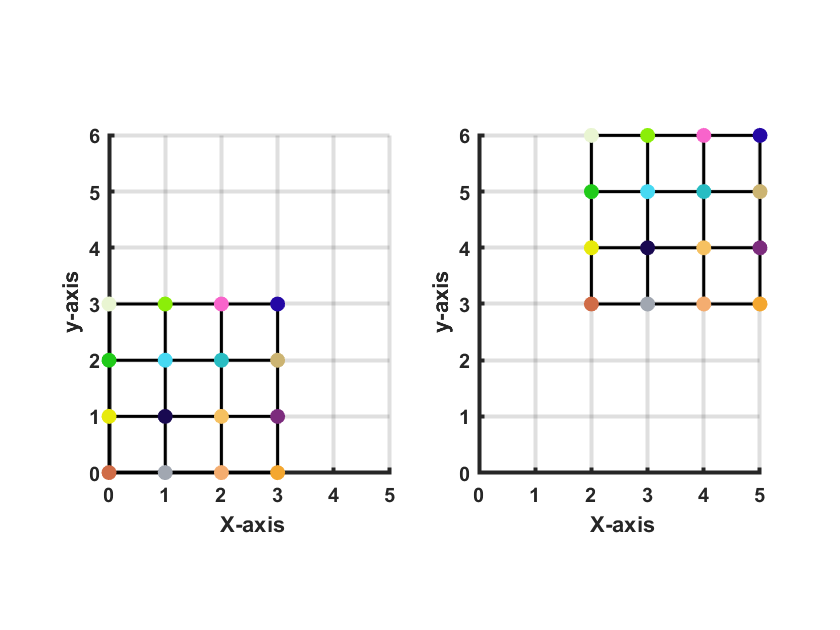


pos_new = HE1*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(1); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);


% rotation 30 degress
theta = 30;
HE2 = eye(3,3);
HE2(1,1) = cosd(theta);
HE2(1,2) = -sind(theta);
HE2(2,1) = sind(theta);
HE2(2,2) = cosd(theta);

HE2

HE2 =       0.86603         -0.5            0
          0.5      0.86603            0
            0            0            1


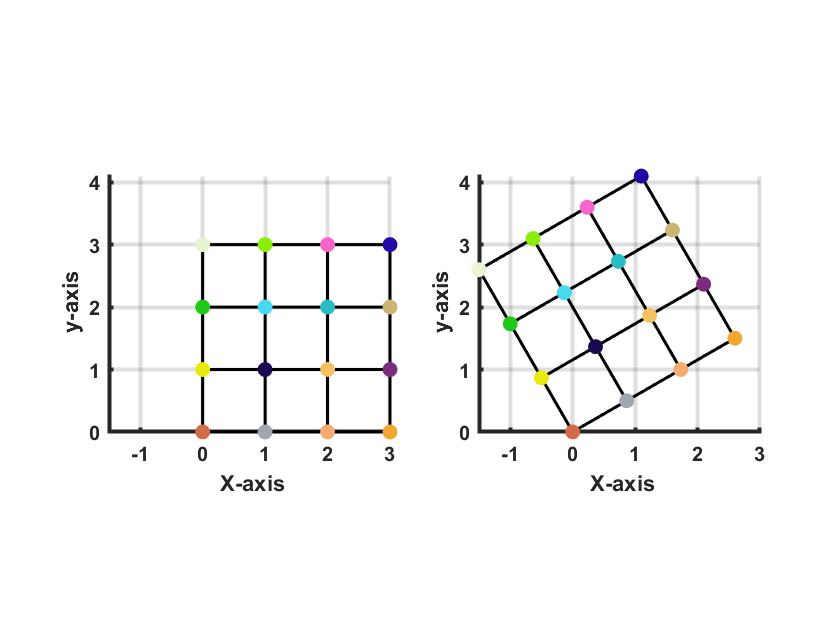


pos_new = HE2*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(2); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);



% rotation 30 degress + transplation (3,4)
theta = 30;
HE3 = eye(3,3);
HE3(1,1) = cosd(theta);
HE3(1,2) = -sind(theta);
HE3(2,1) = sind(theta);
HE3(2,2) = cosd(theta);
HE3(1,3) = 3;
HE3(2,3) = 4;

HE3

HE3 =       0.86603         -0.5            3
          0.5      0.86603            4
            0            0            1


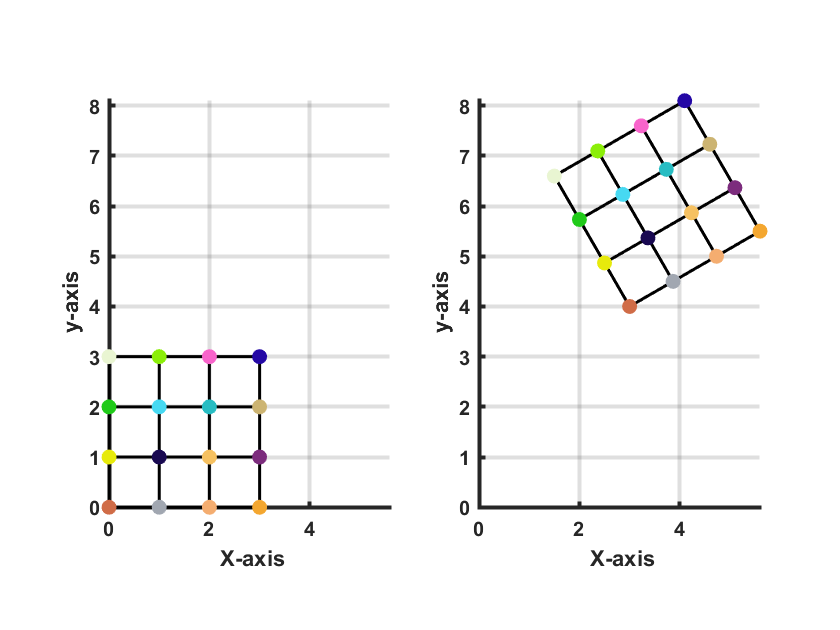


pos_new = HE3*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(3); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

## Similrity Transformation

close all;

n = 4;
[pos, adj, col_dot] = GenGrid(n);

% isometric scaling: X' = 2X 
HS1 = eye(3,3);
HS1(1,1) = 2;
HS1(2,2) = 2;

HS1

HS1 =      2     0     0
     0     2     0
     0     0     1


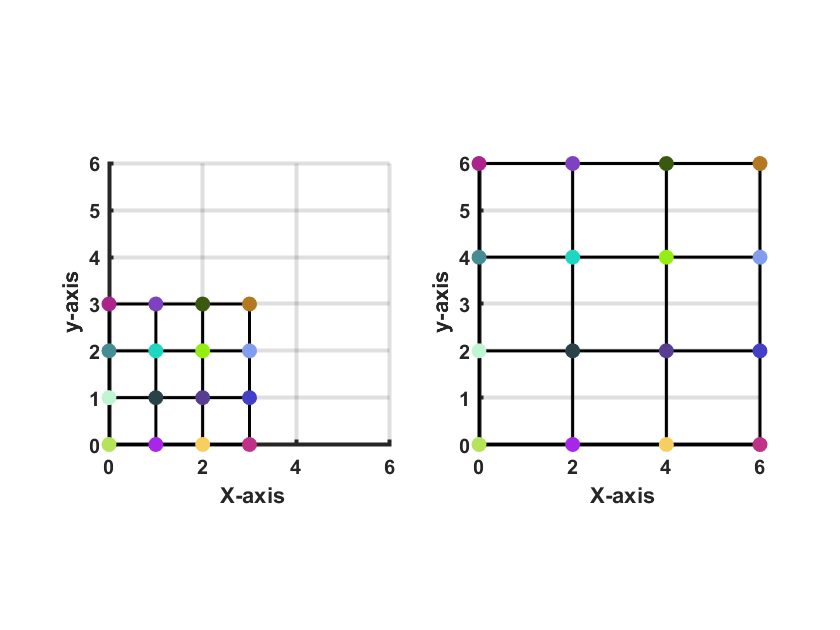


pos_new = HS1*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(1); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);


% isometric scaling: X' = 2X + rotation 30 degress + transplation (3,4)
theta = 30;
scale = 2;
HS2 = eye(3,3);
HS2(1,1) = scale * cosd(theta);
HS2(1,2) = scale * -sind(theta);
HS2(2,1) = scale * sind(theta);
HS2(2,2) = scale * cosd(theta);

HS2(1,3) = 3;
HS2(2,3) = 4;

HS2

HS2 =        1.7321           -1            3
            1       1.7321            4
            0            0            1


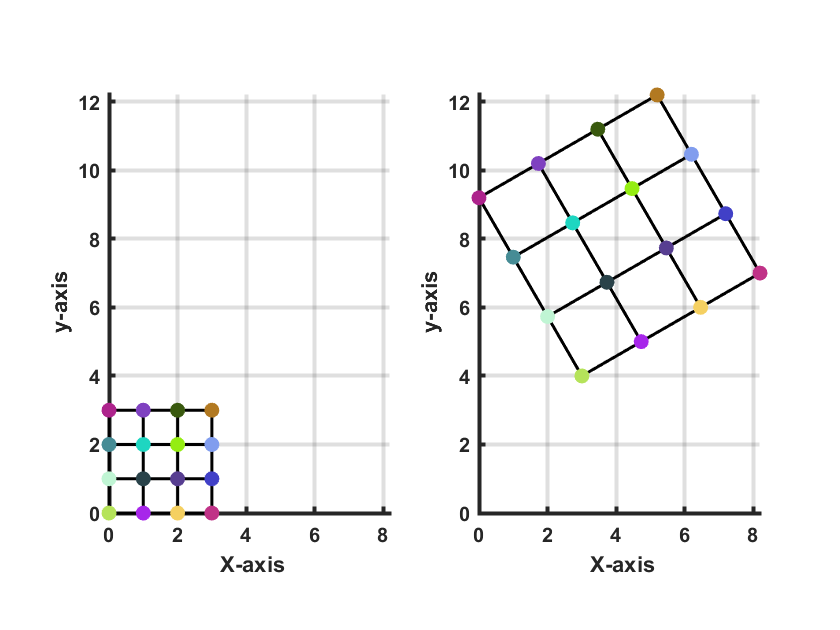


pos_new = HS2*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(2); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

## Affine Transformation

clear; close all;

n = 4;
[pos, adj, col_dot] = GenGrid(n);

% random generation A
A = [1.79 -0.834; 0.1916 1.0265]; 
HA = eye(3,3);
HA(1:2,1:2) = A;

det(A) % should be non-zero

ans =        1.9972



[U, D, V] = svd(A);

if det(U)<0 && det(V)<0  % reflection correction
    U = U*[-1 0;0 1];
    V = V*[-1 0;0 1];
end
A = U*D*V'

A =          1.79       -0.834
       0.1916       1.0265



R_theta = U*V'; 
acosd(R_theta(1,1))

ans =        20.009


asind(-R_theta(1,2))

ans =        20.009


asind(R_theta(2,1))

ans =        20.009


theta = acosd(R_theta(1,1));

R_phi = V';
acosd(R_phi(1,1))

ans =        30.043


asind(-R_phi(1,2))

ans =        30.043


asind(R_phi(2,1))

ans =        30.043


phi = acosd(R_phi(1,1));

Rt = eye(3,3);
Rt(1,1) = cosd(theta);
Rt(2,2) = cosd(theta);
Rt(1,2) = -sind(theta);
Rt(2,1) = sind(theta);

Rp = eye(3,3);
Rp(1,1) = cosd(phi);
Rp(2,2) = cosd(phi);
Rp(1,2) = -sind(phi);
Rp(2,1) = sind(phi);

Dn = eye(3,3);
Dn(1:2,1:2) = D;

HA

HA =          1.79       -0.834            0
       0.1916       1.0265            0
            0            0            1


Rt*Rp'*Dn*Rp

ans =          1.79       -0.834            0
       0.1916       1.0265            0
            0            0            1


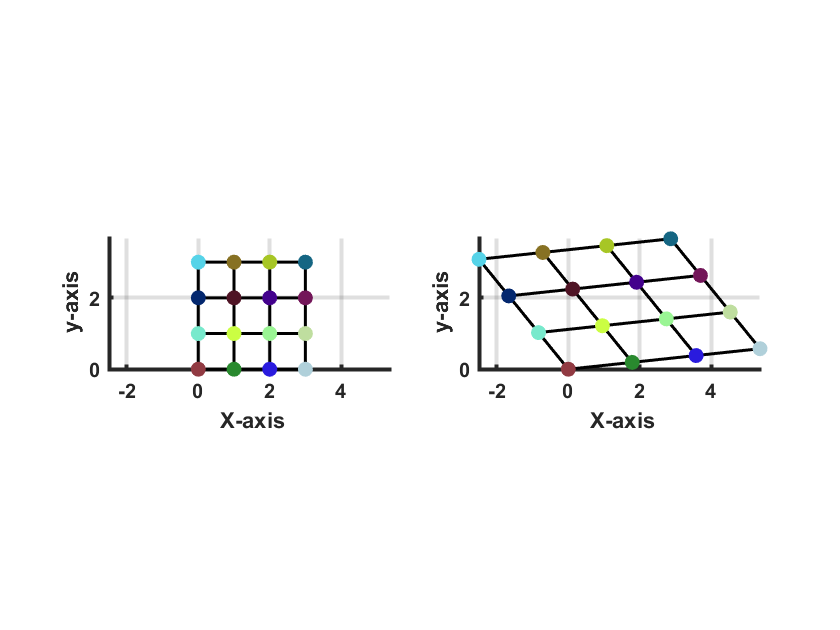


pos_new = HA*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(1); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

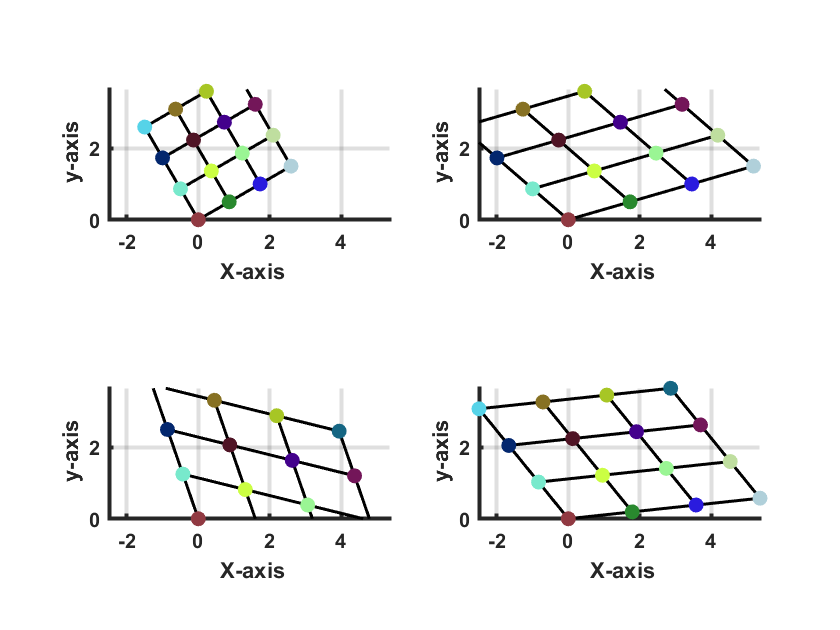



figure(2);
pos_new = Rp*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

subplot(221); DrawGrid(gca, pos_new, adj, col_dot, xylim);

pos_new = Dn*Rp*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

subplot(222); DrawGrid(gca, pos_new, adj, col_dot, xylim);

pos_new = Rp'*Dn*Rp*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

subplot(223); DrawGrid(gca, pos_new, adj, col_dot, xylim);

pos_new = Rt*Rp'*Dn*Rp*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

subplot(224); DrawGrid(gca, pos_new, adj, col_dot, xylim);

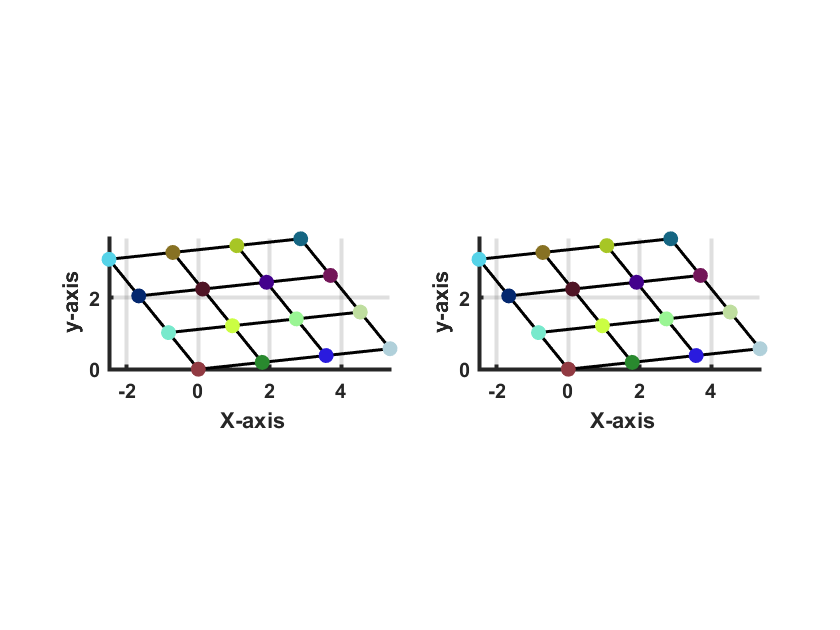


pos_new_svd = pos_new;

figure(3); 

pos_new = HA*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

subplot(121); DrawGrid(gca, pos_new_svd, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);